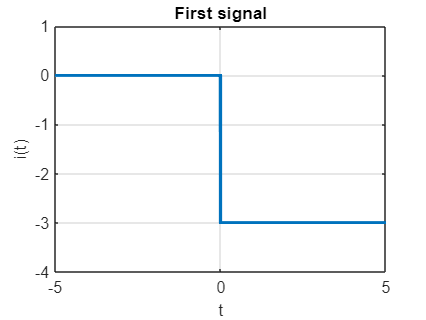

%Ex1
%a.
clear variables;
u0 = @(t)(t>=0);
A=3; 
t=-5:0.001:5;
i=-A*u0(t);
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('First signal');
grid;

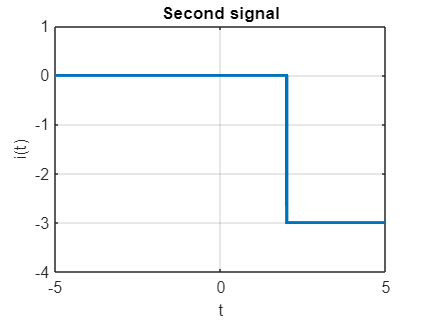


%b.
clear variables;
u0 = @(t)(t>0);
A=3;T=2;
t=-5:0.001:5;
i=-A*u0(t-T);
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('Second signal');
grid;

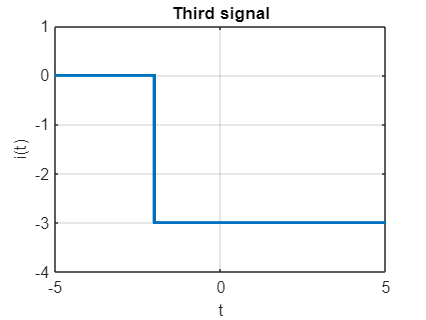


%c.
clear variables;
u0 = @(t)(t>0);
A=3;T=2;
t=-5:0.001:5;
i=-A*u0(t+T);
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('Third signal');
grid;

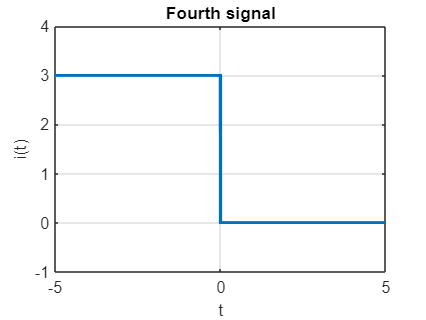


%d.
clear variables;
u0 = @(t)(t>=0);
A=3;t=-5:0.001:5;
i=-A*u0(t)+A;
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('Fourth signal');
grid;

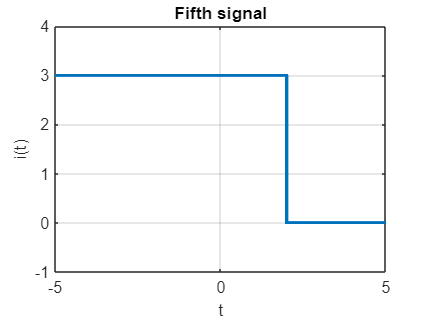


%e.
clear variables;
u0 = @(t)(t>=0);
A=3;T=2;
t=-5:0.001:5;
i=-A*u0(t-T)+A;
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('Fifth signal');
grid;

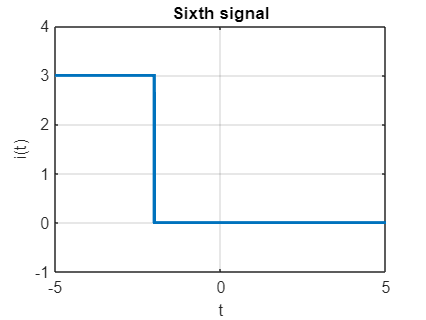


%f.
clear variables;
u0 = @(t)(t>=0);
A=3;T=2;
t=-5:0.001:5;
i=-A*u0(t+T)+A;
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('Sixth signal');
grid;

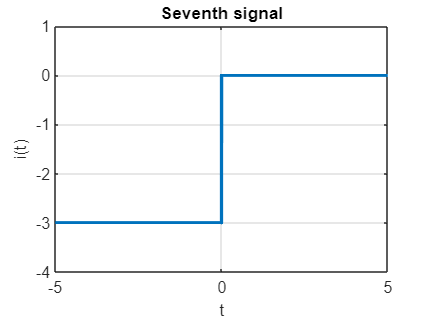


%g.
clear variables;
u0 = @(t)(t>=0);
A=3;
t=-5:0.001:5;
i=A*u0(t)-A;
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('Seventh signal');
grid;

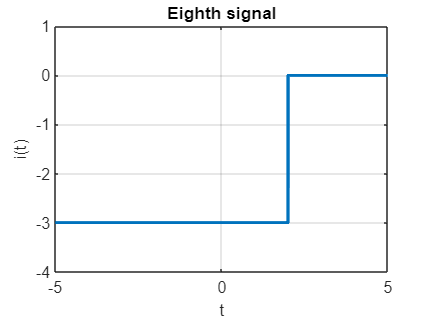


%h.
clear variables;
u0 = @(t)(t>=0);
A=3;T=2;
t=-5:0.001:5;
i=A*u0(t-T)-A;
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('Eighth signal');
grid;

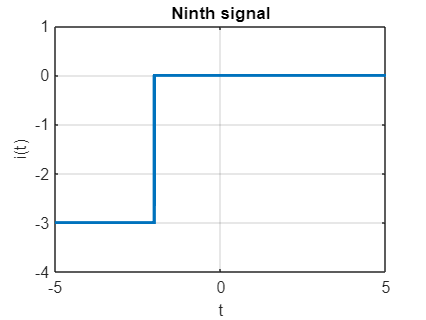


%i.
clear variables;
u0 = @(t)(t>=0);
A=3;T=2;t=-5:0.001:5;
i=A*u0(t+T)-A;
plot(t,i,'LineWidth',2);
axis([min(t),max(t),min(i)-1,max(i)+1]);
xlabel('t'); ylabel('i(t)');
title('Ninth signal');
grid;

Exercise 2

a)


$$\int_{-4}^7 \sin \left(\pi t\right)\delta \left(t-1\right)\textrm{dt}=\sin \left(\pi \right)=0$$


 b)


$$\int_0^2 \sin \left(\pi t\right)\delta \left(t-3\right)\textrm{dt}=0\;\textrm{directly},\textrm{because}\;t=3\;\textrm{for}\;\textrm{which}\;\delta \left(t-3\right)\not= 0\;\textrm{is}\;\textrm{not}\;\textrm{in}\;\textrm{the}\;\textrm{integration}\;\textrm{interval}$$


c) $e^{-t} \cos \left(10t\right)\delta \left(t\right)=1$


$$\delta \left(t\right)\not= 0\;\textrm{and}=1\;\textrm{only}\;\textrm{when}\;t=0,\textrm{for}\;t=0\to e^{-t} \cos \left(10t\right)=1\;$$


d) $\sin \left(2\pi \right)\sum_{k=0}^{\infty } \delta \left(t-k\right),\;k\;\epsilon \;Z=0$

If $t<0,\sum_{k=0}^{\infty } \delta \left(t-k\right)=0$

If  $t\ge 0,\sin \left(2\pi t\right)=0$

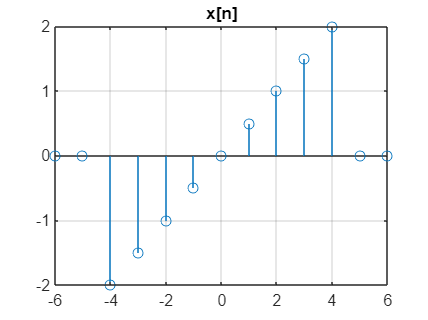

%Ex3
clear variables

n = -6:6;
u0 = @(n) (n>=0);
x = @(n) ((n/2) .* u0(n+4) - u0(n-5) .* (n/2));

figure, stem(n, x(n));
title('x[n]'); grid

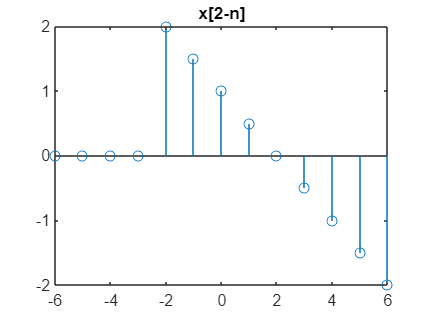


%a)
stem(n,x(2-n));
title('x[2-n]');

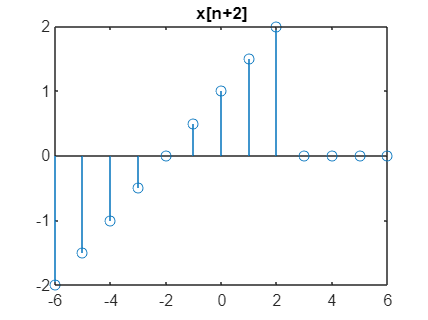


%b)
stem(n,x(n+2));
title('x[n+2]');

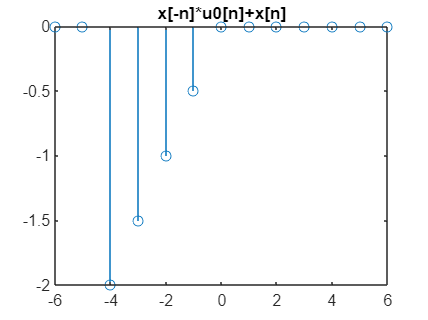


%c)
stem(n,x(-n).*u0(n)+x(n));
title('x[-n]*u0[n]+x[n]');

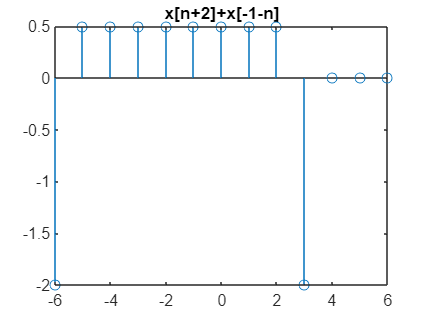


%d)
stem(n,x(n+2)+x(-1-n));
title('x[n+2]+x[-1-n]');

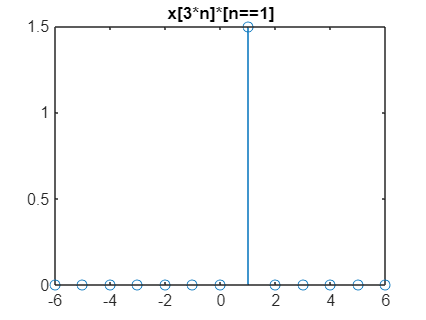


%e)
stem(n,x(3*n).*(n==1));
title('x[3*n]*[n==1]');

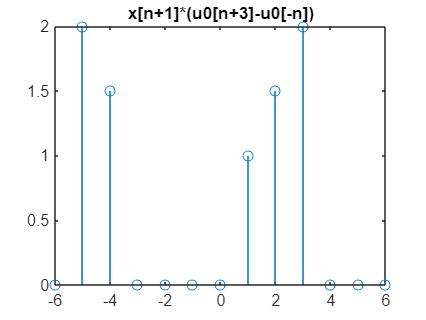


%f)
stem(n,x(n+1).*(u0(n+3)-u0(-n)));
title('x[n+1]*(u0[n+3]-u0[-n])');

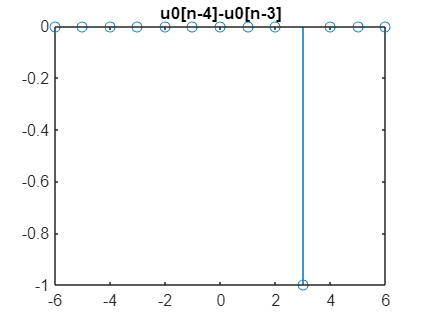


%g)
stem(n,u0(n-4)-u0(n-3));
title('u0[n-4]-u0[n-3]');